# Data preparation

## Load the data

We load the original dataset in '../RobotPdMDataset', and create two cell arrays:

- X: A cellarray of 2000 elements, each element is a 1000*6 matrix, that contains the x, y, z coordiates of the desired and response trajectories, respetively.

- y: A cellarray of 2000 elements, each element is the label (str).

clear; clc; close all;

doTraining = true;

mdl_name = 'finalMdlTrajCmdTrajResidual.mat';
% Define the path to check for the logged data.
training_data_name = 'all_training_dataset.mat';
training_data_path = '../RobotPdMDataset';

% Set random seed for reproduction purpose.
rng(10);

datasetPath = fullfile(training_data_path, training_data_name);
% Check if the file exists
if isfile(datasetPath)
    % If the file exists, load the dataset
    load(datasetPath, 'X', 'y');
    disp('Loaded data from logged data.');
else
    % If the file does not exist, run read_original_data
    [X, y] = read_original_data(training_data_path);
    
    % Save X and y as 'conc_dataset.mat' under '../RobotPdMDataset'
    save(datasetPath, 'X', 'y');
    disp(['Data generated and saved as ' training_data_name]);
end

Loaded data from logged data.


% Shuffle the dataset using the cvpartition function
training_ratio = .9;
n_dataset = numel(X);
training_size = floor(training_ratio*n_dataset);
cvObj = cvpartition(y, 'HoldOut', training_size);
idx = cvObj.test;

% Split into training and test data based on training size specified
X_train_org = X(idx');
X_val_org = X(~idx');
y_train = categorical(y(idx'));
y_val = categorical(y(~idx'));

% Get the training data

testing_data_name = 'real_testing_dataset.mat';
testing_data_path = 'Real_test_data_1/';
datasetPath = fullfile(testing_data_path, testing_data_name);
% Check if the file exists
if isfile(datasetPath)
    % If the file exists, load the dataset
    load(datasetPath, 'X_test_org', 'y_test');
    disp('Loaded data from logged data.');
else
    % If the file does not exist, run read_original_data
    [X_test_org, y_test] = read_original_data(testing_data_path);
    
    % Save X and y as 'conc_dataset.mat' under '../RobotPdMDataset'
    save(datasetPath, 'X_test_org', 'y_test');
    disp(['Data generated and saved as ' testing_data_name]);
end

Loaded data from logged data.


y_test = categorical(y_test);

## Training and validation set creation

We randomly split a dataset and train a LSTM.

We can show the distribution of classes in the training and testing dataset, to make sure the seperation is fair.

summary(y_train);

     Healthy      Motor_1_Steady_state_error      Motor_1_Stuck      Motor_2_Steady_state_error      Motor_2_Stuck      Motor_3_Steady_state_error      Motor_3_Stuck      Motor_4_Steady_state_error      Motor_4_Stuck 
     360          360                             360                360                             360                360                             360                360                             360           


summary(y_val);

     Healthy      Motor_1_Steady_state_error      Motor_1_Stuck      Motor_2_Steady_state_error      Motor_2_Stuck      Motor_3_Steady_state_error      Motor_3_Stuck      Motor_4_Steady_state_error      Motor_4_Stuck 
     40           40                              40                 40                              40                 40                              40                 40                              40            


summary(y_test);

     Healthy      Motor_1_Steady_state_error      Motor_1_Stuck      Motor_2_Steady_state_error      Motor_2_Stuck      Motor_3_Steady_state_error      Motor_3_Stuck      Motor_4_Steady_state_error      Motor_4_Stuck 
     10           10                              10                 10                              10                 10                              10                 10                              10            


# Pre-processing and feature engineering

In this section, we preprocess the data and augument the dataset by adding some new features from feature engineering.

% X_train = filtering(X_train_org);
% X_val = filtering(X_val_org);
% X_test = filtering(X_test_org);
% 
% idx = 3;
% label_list = {'Healthy', 'Motor_1_Stuck', 'Motor_2_Stuck', 'Motor_3_Stuck', 'Motor_4_Stuck', ...
%     'Motor_1_Steady_state_error', 'Motor_2_Steady_state_error', 'Motor_3_Steady_state_error', 'Motor_4_Steady_state_error'}; % Define the labels to be simulated.
% label = label_list{idx}
% exampleDistribution(X_train, X_val, X_test, y_train, y_val, y_test, label);

% X_train = max_min_norm(X_train);
% X_val = max_min_norm(X_val);
% X_test = max_min_norm(X_test);
% 
% exampleDistribution(X_train, X_val, X_test, y_train, y_val, y_test, label);

% X_train = generate_random_noise(X_train);
% X_val = generate_random_noise(X_val);
% 
% exampleDistribution(X_train, X_val, X_test, y_train, y_val, y_test, label);


[X_train, M, S] = preprocessing(X_train_org);
[X_val, ~, ~] = preprocessing(X_val_org);
[X_test, ~, ~] = preprocessing(X_test_org);
% [X_val, ~, ~] = preprocessing(X_val_org, M, S);
% [X_test, ~, ~] = preprocessing(X_test_org, M, S);

% exampleDistribution(X_train, X_val, X_test, y_train, y_val, y_test, label);

## Explore the feature distribution

X_train = generate_random_noise(X_train);
X_val = generate_random_noise(X_val);

% label = 'Healthy'
% exampleDistribution(X_train, X_val, X_test, y_train, y_val, y_test, label);

# Training and evaluating the model

Use an LSTM network. An LSTM layer learns long-term dependencies between time steps of time series or sequence data. The first lstmlayer will have 100 hidden units and output the sequence data. Then a dropout layer will be used to reduce probability of overfitting. The second lstmlayer will output just the last step of the time sequence.

layers = [ ...
    sequenceInputLayer(size(X_train{1},1))
    lstmLayer(100,"OutputMode","sequence")
    dropoutLayer(0.1)
    lstmLayer(100,"OutputMode","last")
    fullyConnectedLayer(numel(categories(y_train)))
    softmaxLayer
    classificationLayer];

## Define Network Hyperparameters

miniBatchSize = 32;
validationFrequency = floor(numel(X_train)/miniBatchSize);
options = trainingOptions("adam", ...
    "MaxEpochs",30, ...
    "MiniBatchSize",miniBatchSize, ...
    "Plots","training-progress", ...
    "Verbose",false, ...
    "Shuffle","every-epoch", ...
    "LearnRateSchedule","piecewise", ...
    "LearnRateDropFactor",0.1, ...
    "LearnRateDropPeriod",20,...
    'ValidationData',{X_val, y_val}, ...
    'ValidationFrequency',validationFrequency);

## Train The Network

This network takes about 100 seconds to train on an NVIDIA RTX 2080 GPU.

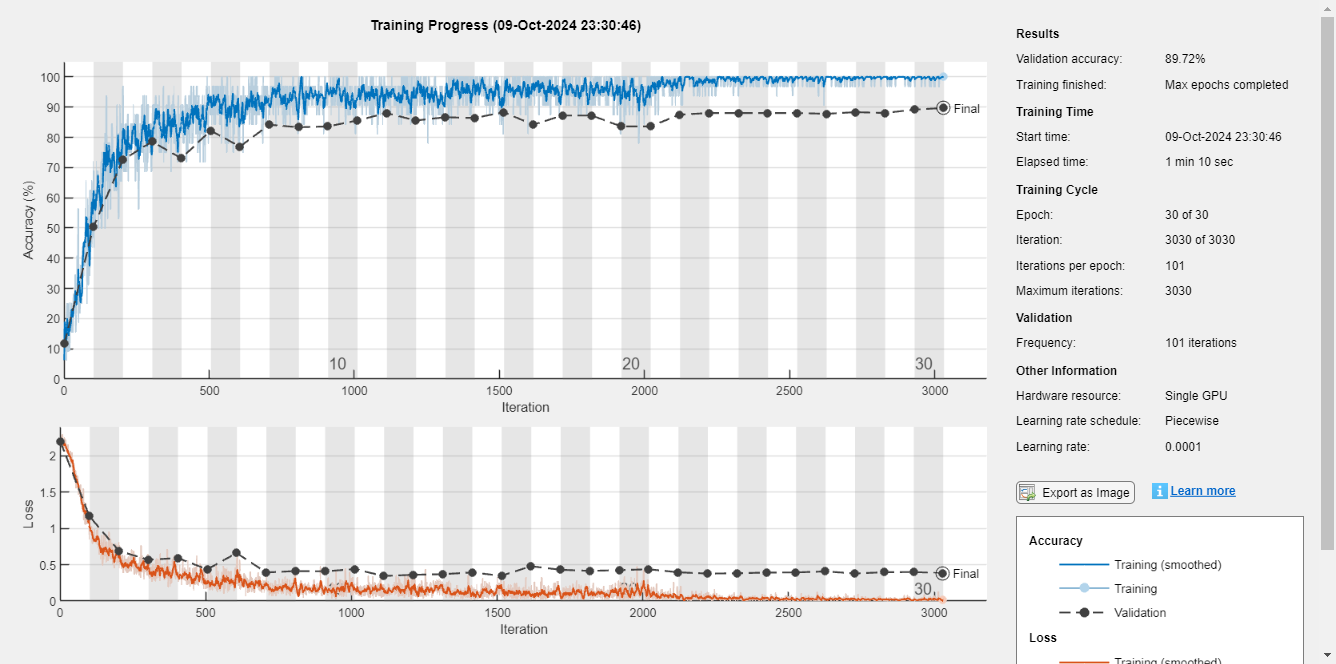

if doTraining
    diagnosisNet = trainNetwork(X_train, y_train, layers, options);
    save(mdl_name, 'diagnosisNet');
else
    load(mdl_name, 'diagnosisNet');
end

## Test The Network

Now that the network has been trained, we can test it on the validation data. 

y_pred = classify(diagnosisNet, X_test);

View the confusion chart for the test results:

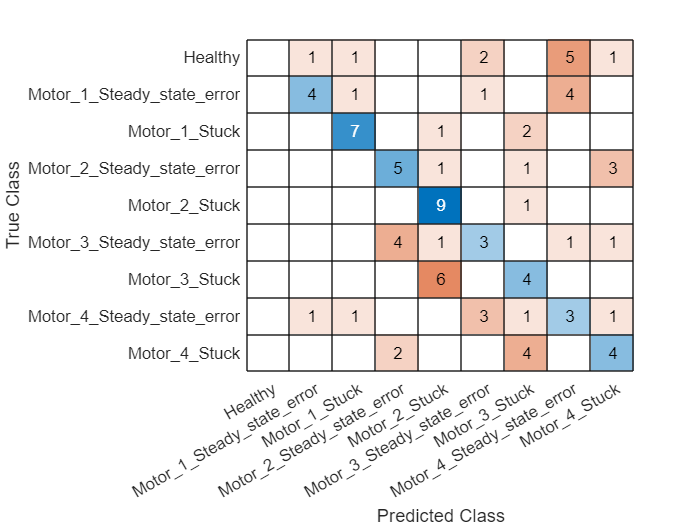

cm = confusionchart(y_test', y_pred);

View the overall accuracy percentage of the validation and test results:

[accuracy, precision, recall, f1Score] = eval_perf(y_test, y_pred);
% Display the results
fprintf('Overall Accuracy: %.2f%%\n', accuracy * 100);

Overall Accuracy: 43.33%


class_names = categories(y_test);
for i = 1:numel(class_names)
    fprintf('Class %d (%s): Precision = %.2f, Recall = %.2f, F1 Score = %.2f\n', i, class_names{i}, precision(i), recall(i), f1Score(i));
end

Class 1 (Healthy): Precision = NaN, Recall = 0.00, F1 Score = NaN
Class 2 (Motor_1_Steady_state_error): Precision = 0.67, Recall = 0.40, F1 Score = 0.50
Class 3 (Motor_1_Stuck): Precision = 0.70, Recall = 0.70, F1 Score = 0.70
Class 4 (Motor_2_Steady_state_error): Precision = 0.45, Recall = 0.50, F1 Score = 0.48
Class 5 (Motor_2_Stuck): Precision = 0.50, Recall = 0.90, F1 Score = 0.64
Class 6 (Motor_3_Steady_state_error): Precision = 0.33, Recall = 0.30, F1 Score = 0.32
Class 7 (Motor_3_Stuck): Precision = 0.31, Recall = 0.40, F1 Score = 0.35
Class 8 (Motor_4_Steady_state_error): Precision = 0.23, Recall = 0.30, F1 Score = 0.26
Class 9 (Motor_4_Stuck): Precision = 0.40, Recall = 0.40, F1 Score = 0.40


# Some diagnosis

Try to see if there is some distributional difference among the training and testing data.

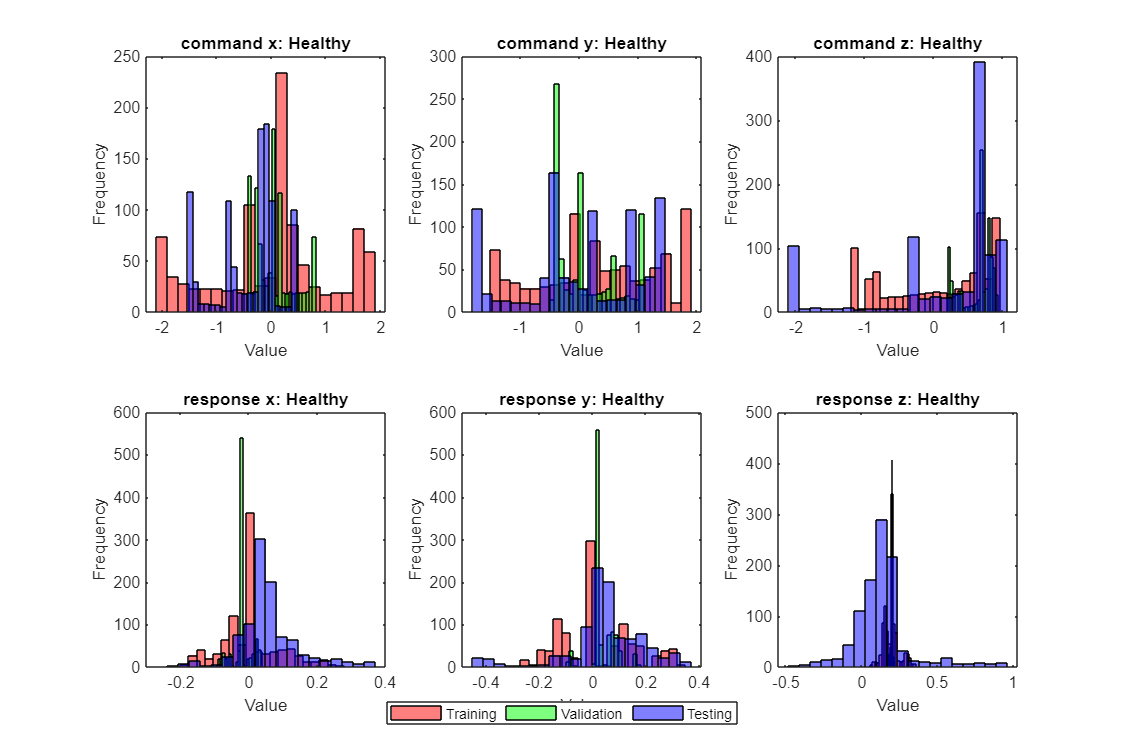

Healthy
training (mean):
    0.0296    0.3322    0.0817    0.0043    0.0213    0.1991

validation (mean):
    0.0619    0.1543    0.6298   -0.0189    0.0383    0.2006

Test (mean):
   -0.3911    0.0290    0.1679    0.0595    0.0486    0.1345

training (std):
    1.0841    1.0235    0.7198    0.0849    0.1420    0.0493

validation (std):
    0.3622    0.5116    0.2198    0.0281    0.0466    0.0078

Test (std):
    0.5629    1.0131    0.9319    0.0890    0.1473    0.1902



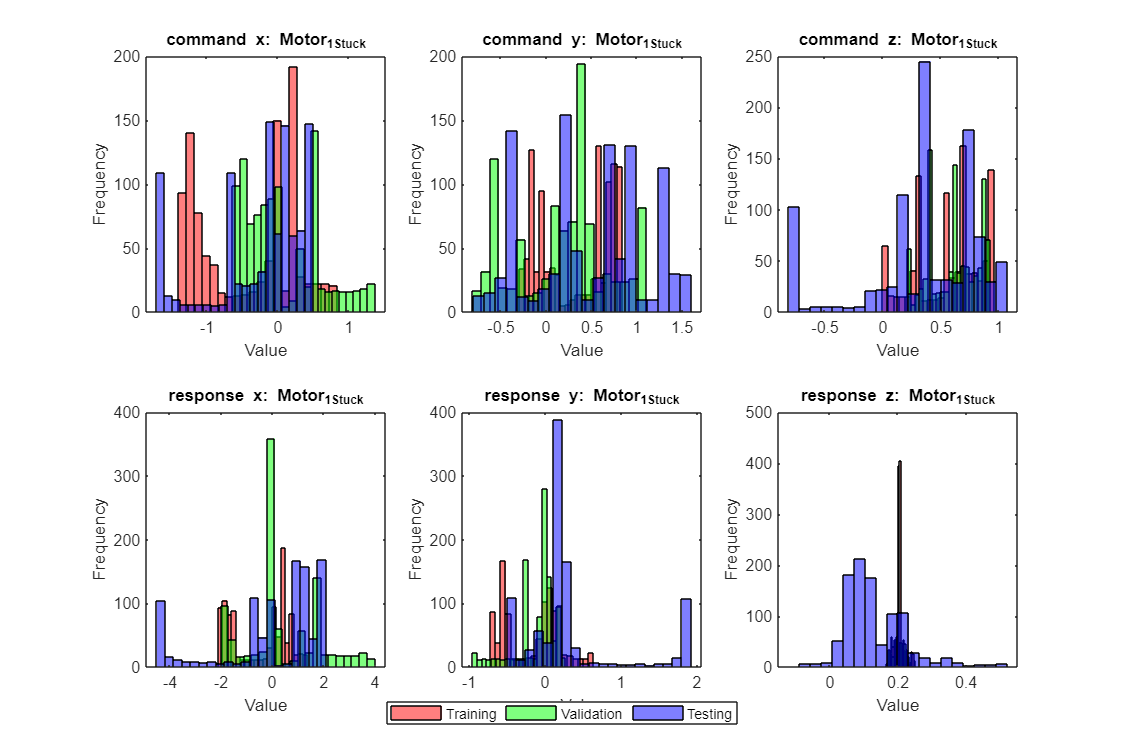

Motor_1_Stuck
training (mean):
   -0.3943    0.3351    0.5676   -0.4767   -0.1563    0.2047

validation (mean):
    0.0605    0.1911    0.6131    0.4138   -0.1160    0.2032

Test (mean):
   -0.2526    0.4862    0.3435   -0.0329    0.3397    0.1335

training (std):
    0.6899    0.3957    0.2708    1.0851    0.3670    0.0163

validation (std):
    0.5226    0.5136    0.2101    1.4024    0.2599    0.0138

Test (std):
    0.6575    0.6195    0.4886    1.9493    0.6522    0.0911



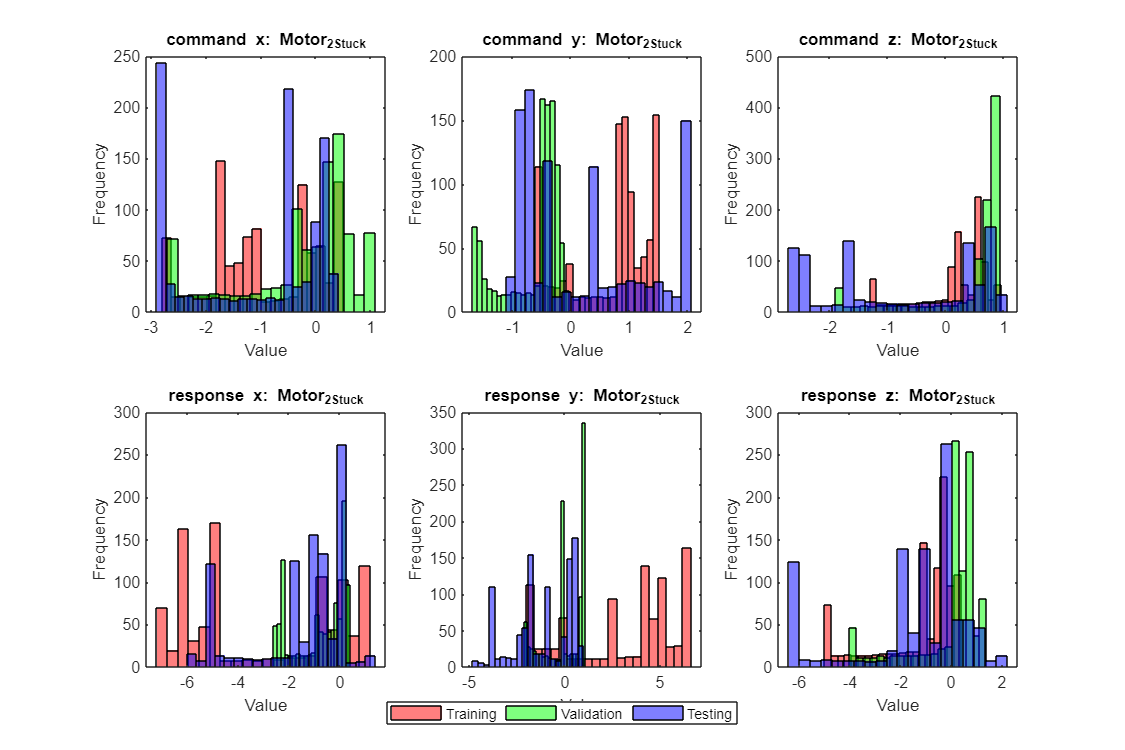

Motor_2_Stuck
training (mean):
   -0.9517    0.7015    0.1526   -3.0244    3.1189   -1.2183

validation (mean):
   -0.2711   -0.6353    0.3899   -0.7733    0.0692   -0.1034

Test (mean):
   -1.1060    0.2250   -0.8103   -1.4978   -1.1292   -1.4450

training (std):
    0.9740    0.6617    0.5834    2.8865    2.8402    1.5605

validation (std):
    1.0447    0.4815    0.7857    1.0076    1.0024    1.3283

Test (std):
    1.2071    1.0629    1.3433    1.8229    1.5234    2.1836



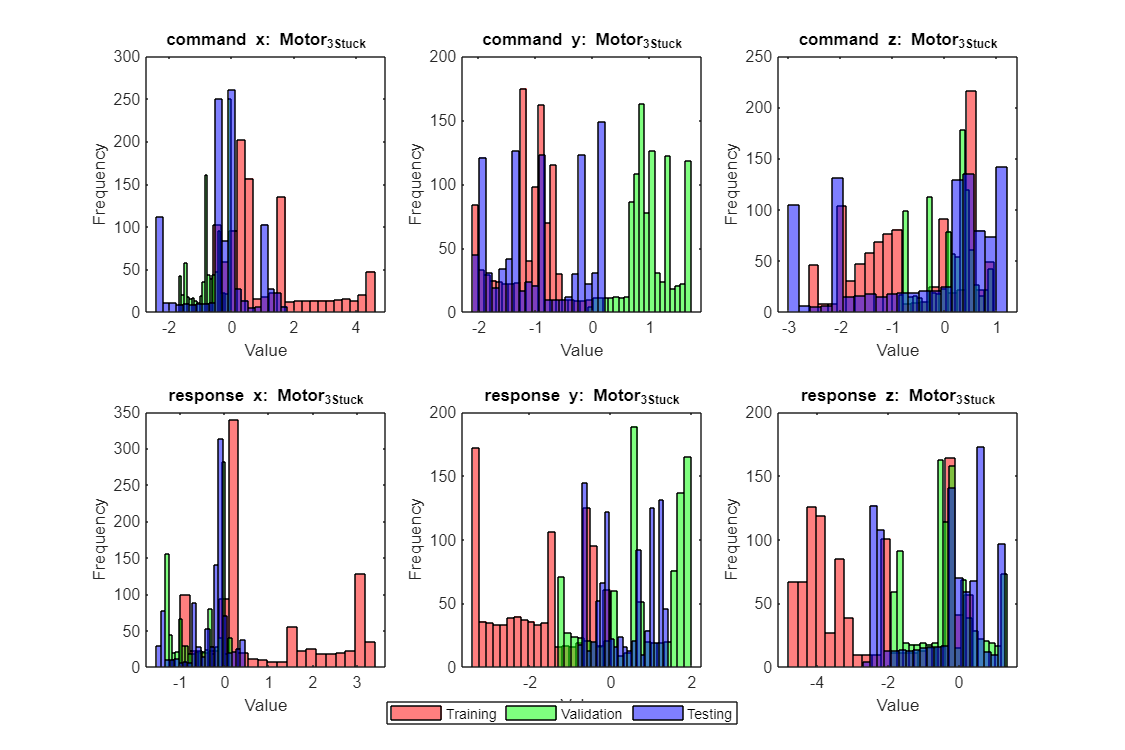

Motor_3_Stuck
training (mean):
    1.0513   -1.1211   -0.6680    0.8834   -1.7466   -2.4851

validation (mean):
   -0.6279    1.0401    0.1127   -0.5194    0.7505   -0.3430

Test (mean):
   -0.2659   -0.9066   -0.3996   -0.3335    0.3494   -0.4529

training (std):
    1.3542    0.4589    1.0409    1.3395    1.1178    1.7280

validation (std):
    0.4954    0.3786    0.4606    0.5129    1.0151    0.8579

Test (std):
    1.0141    0.7635    1.3719    0.4892    0.6994    1.2045



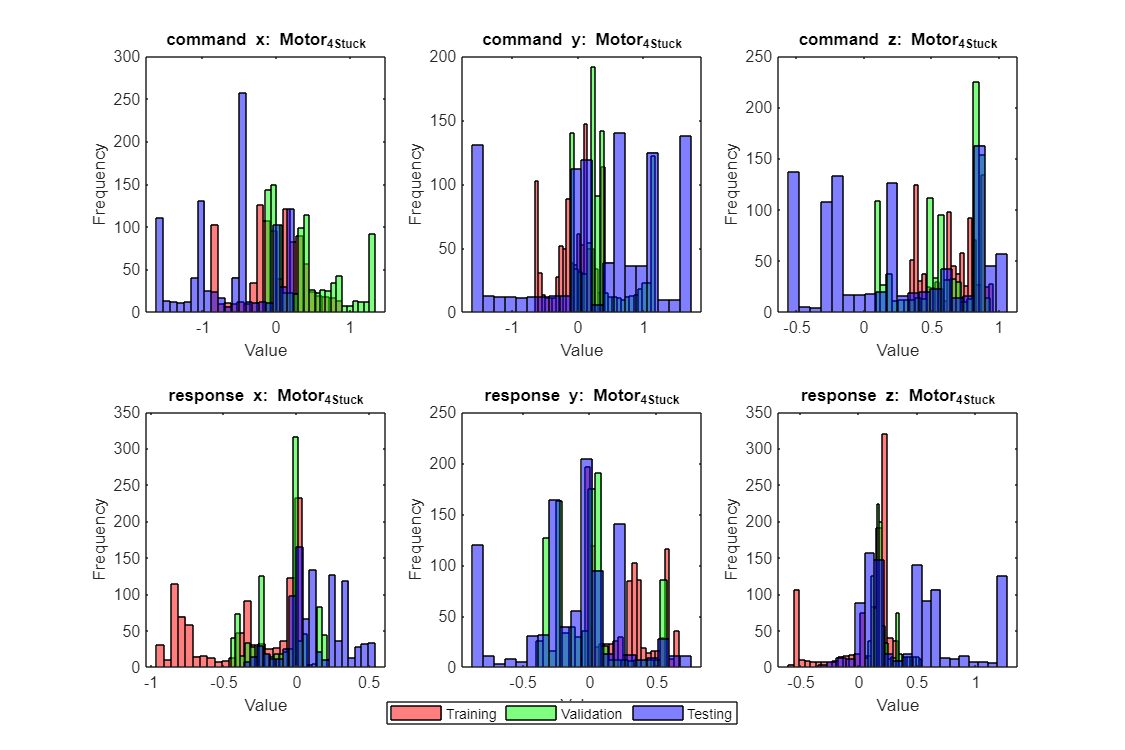

Motor_4_Stuck
training (mean):
   -0.0146   -0.0512    0.6601   -0.3526    0.2612    0.0528

validation (mean):
    0.3829    0.3967    0.5884   -0.1003   -0.0215    0.2151

Test (mean):
   -0.5916    0.3088    0.2188    0.1354   -0.1202    0.4548

training (std):
    0.4047    0.3123    0.1850    0.3380    0.2228    0.2609

validation (std):
    0.4555    0.4014    0.2680    0.1850    0.2513    0.1026

Test (std):
    0.5697    1.0050    0.5364    0.1933    0.3735    0.3935



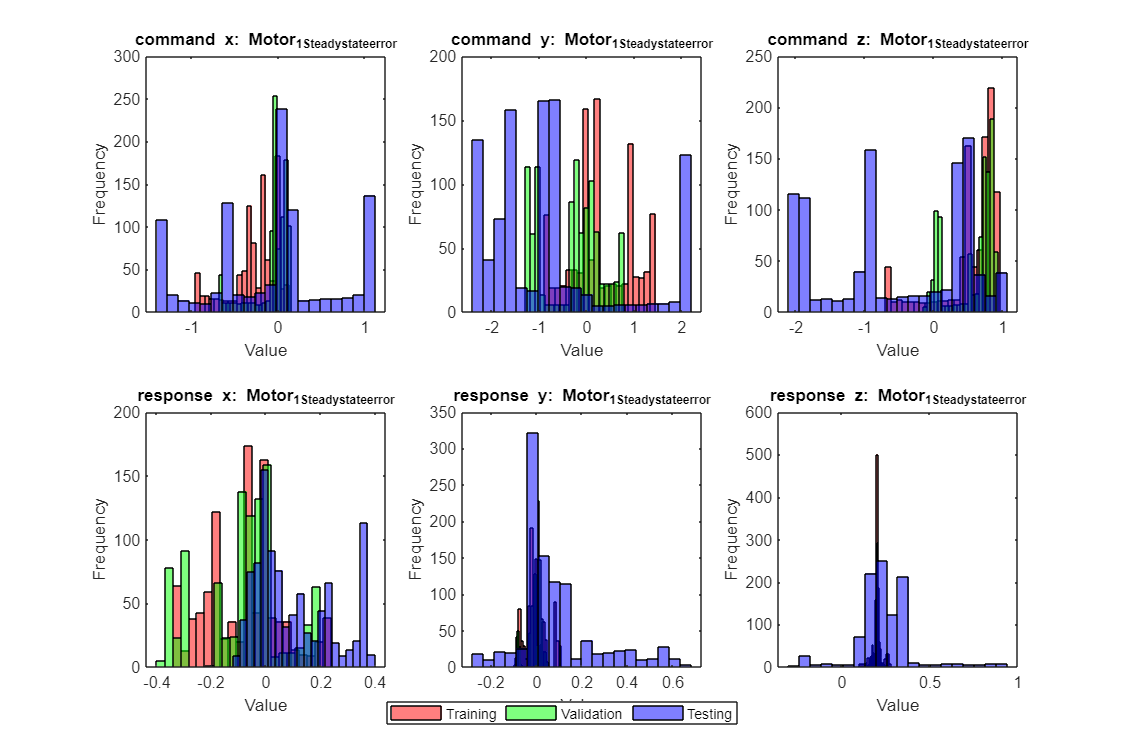

Motor_1_Steady_state_error
training (mean):
   -0.2679    0.3119    0.5463   -0.0787   -0.0017    0.2057

validation (mean):
   -0.0550   -0.2948    0.5613   -0.0813   -0.0044    0.1989

Test (mean):
   -0.0867   -0.7857   -0.5255    0.1054    0.0837    0.2530

training (std):
    0.2691    0.6536    0.4132    0.1387    0.0511    0.0283

validation (std):
    0.2074    0.6236    0.3283    0.1473    0.0292    0.0148

Test (std):
    0.7209    1.3697    1.0028    0.1413    0.1748    0.1643



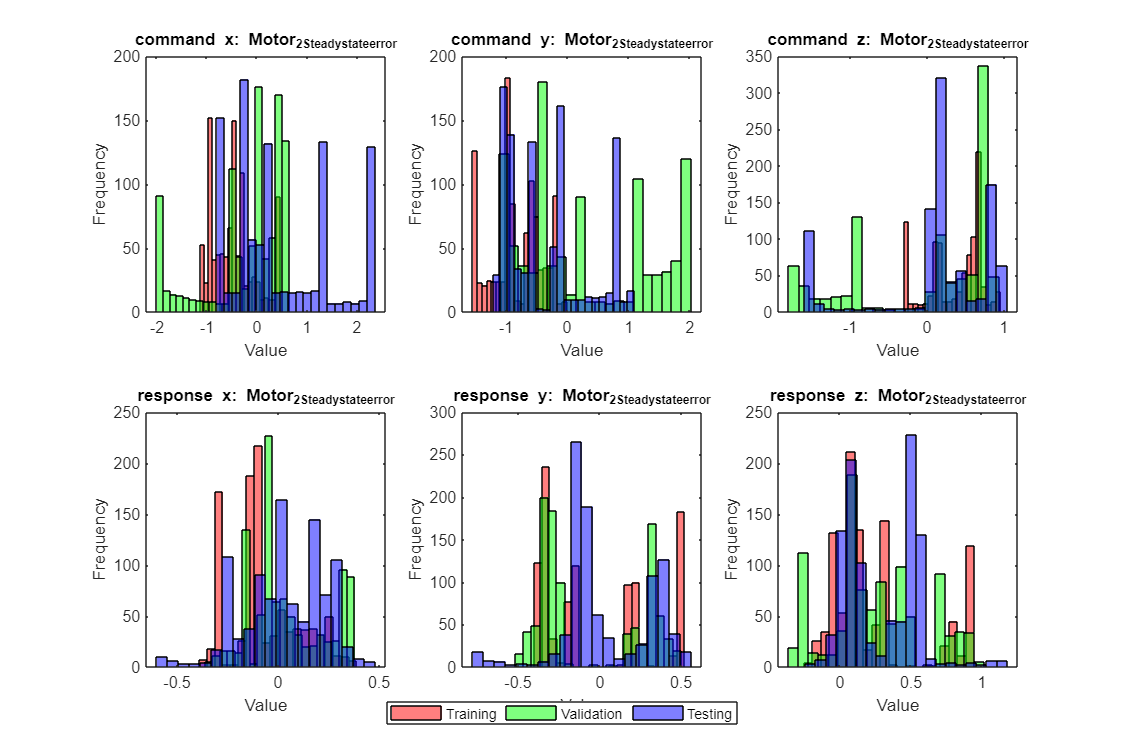

Motor_2_Steady_state_error
training (mean):
   -0.4574   -0.8150    0.3712   -0.0688   -0.0313    0.2583

validation (mean):
   -0.2096    0.3199   -0.0076    0.0466   -0.0690    0.2706

Test (mean):
    0.4646   -0.3323    0.1218    0.0367    0.0279    0.2928

training (std):
    0.4278    0.4052    0.3500    0.1732    0.3301    0.3316

validation (std):
    0.7756    1.0334    0.8838    0.1885    0.3204    0.3387

Test (std):
    1.0211    0.6747    0.7216    0.1990    0.2784    0.2519



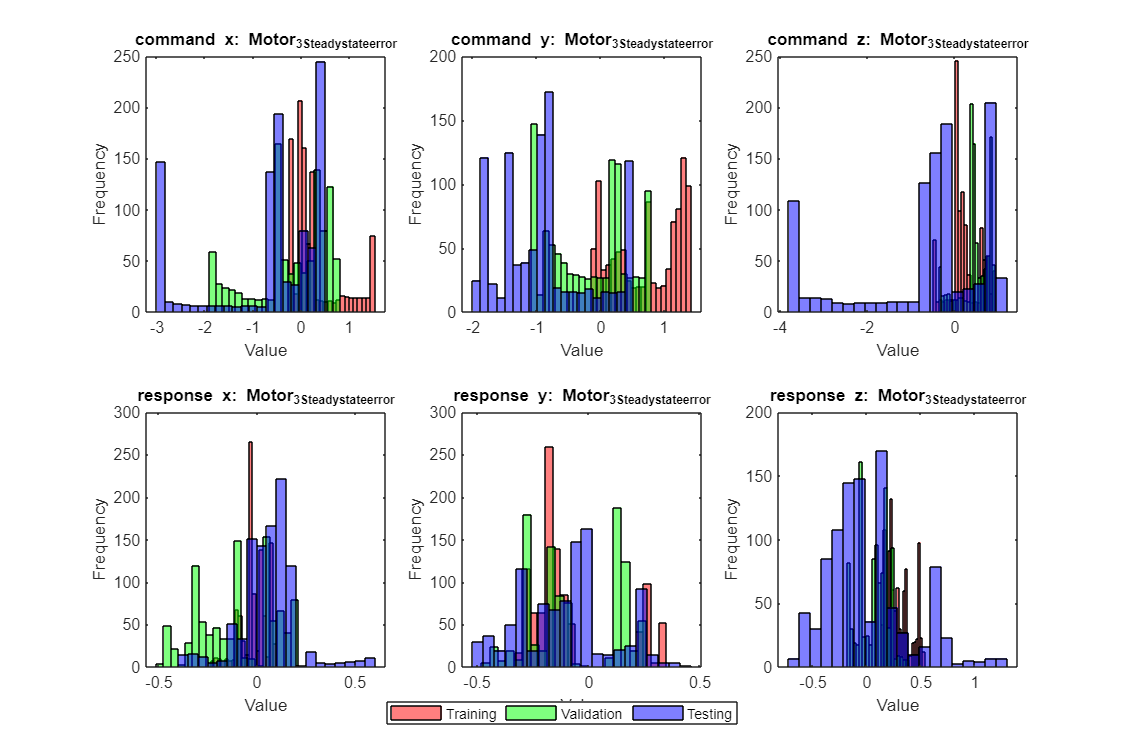

Motor_3_Steady_state_error
training (mean):
    0.2858    0.7205    0.2305   -0.0170   -0.0903    0.2965

validation (mean):
   -0.1852   -0.1636    0.4774   -0.0981   -0.0658    0.0706

Test (mean):
   -0.6327   -0.8727   -0.6385    0.0563   -0.0944    0.0280

training (std):
    0.5154    0.5205    0.3571    0.0691    0.1898    0.1111

validation (std):
    0.7697    0.5985    0.3253    0.1957    0.1980    0.1331

Test (std):
    1.1381    0.7140    1.4263    0.1477    0.2032    0.3741



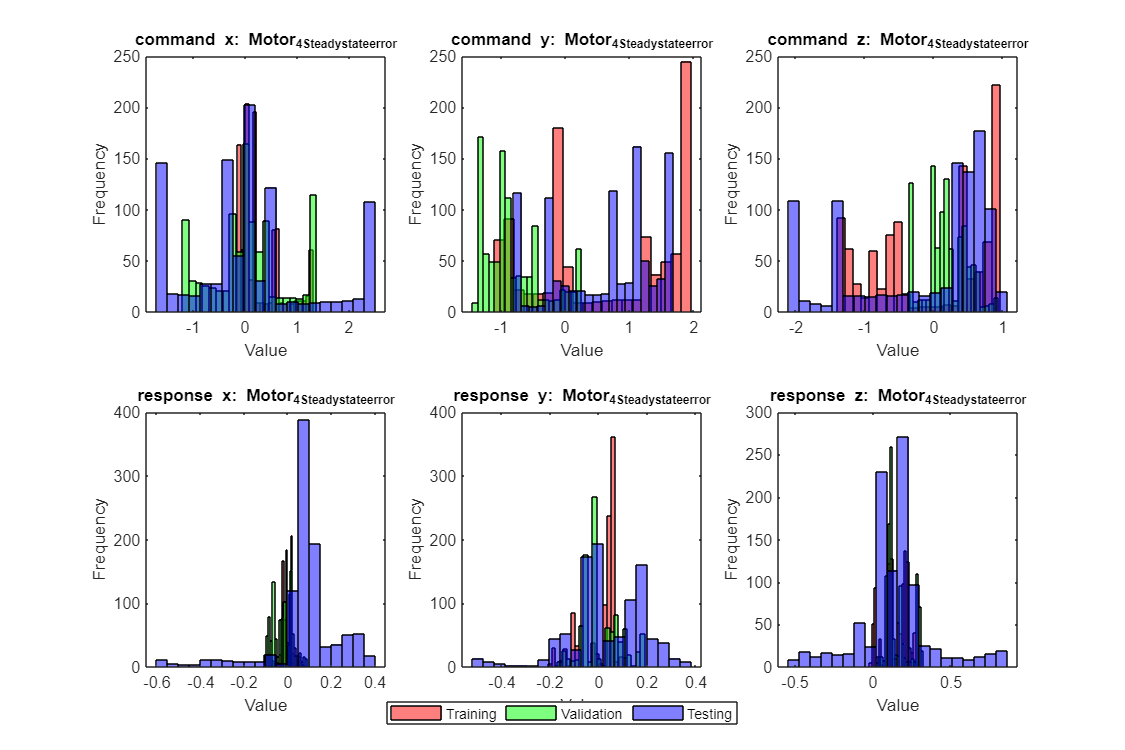

Motor_4_Steady_state_error
training (mean):
    0.2976    0.6330   -0.0448    0.0011    0.0120    0.1470

validation (mean):
    0.0593   -0.7993    0.1836   -0.0239    0.0088    0.1600

Test (mean):
    0.0991    0.6448   -0.1594    0.0814    0.0325    0.1443

training (std):
    0.4117    1.0894    0.8411    0.0238    0.0745    0.0787

validation (std):
    0.7158    0.4619    0.2983    0.0461    0.0797    0.0773

Test (std):
    1.1428    0.7751    1.0069    0.1601    0.1568    0.2295



label_list = {'Healthy', 'Motor_1_Stuck', 'Motor_2_Stuck', 'Motor_3_Stuck', 'Motor_4_Stuck', ...
    'Motor_1_Steady_state_error', 'Motor_2_Steady_state_error', 'Motor_3_Steady_state_error', 'Motor_4_Steady_state_error'}; % Define the labels to be simulated.

for idx = 1:9
    label = label_list{idx};

    plt_feature_dist(X_train, X_val, X_test, y_train, y_val, y_test, label);
end

function plt_feature_dist(X_train, X_val, X_test, y_train, y_val, y_test, label)

f1 = figure();
f1.Position = [10 10 900 600];
X_exp_tr = X_train(y_train==label);
X_exp_val = X_val(y_val==label);
X_exp_test = X_test(y_test==label);

X_exp_tr = X_exp_tr{:};
X_exp_val = X_exp_val{:};
X_exp_test = X_exp_test{:};

titles = {'command x', 'command y', 'command z',...
    'response x', 'response y', 'response z'};

numBins = 20;
for i = 1:6
    subplot(2, 3, i);

    x1 = X_exp_tr(:, i);
    x2 = X_exp_val(:, i);
    x3 = X_exp_test(:, i);

    % Plot the histograms
    histogram(x1, numBins, 'FaceColor', 'r', 'FaceAlpha', 0.5);  % Red histogram
    hold on;  % Keep the current plot
    histogram(x2, numBins, 'FaceColor', 'g', 'FaceAlpha', 0.5);  % Green histogram
    histogram(x3, numBins, 'FaceColor', 'b', 'FaceAlpha', 0.5);  % Blue histogram
    hold off;  % Release the plot hold

    % Add labels
    xlabel('Value');
    ylabel('Frequency');
    title([titles{i} ': ' label]);
end
legend('Training', 'Validation', 'Testing', 'Position', [0.5 0.05 0 0], 'Orientation', 'horizontal');

disp(label);
disp('training (mean):')
disp(mean(X_exp_tr))
disp('validation (mean):')
disp(mean(X_exp_val))
disp('Test (mean):')
disp(mean(X_exp_test))

disp('training (std):')
disp(std(X_exp_tr))
disp('validation (std):')
disp(std(X_exp_val))
disp('Test (std):')
disp(std(X_exp_test))


end

# Supporting functions

function [X_shuffled, y_shuffled] = read_original_data(mainFolder, shuffle)
    % This function reads the original data under path mainFolder. 
    % It will shuffle the data, and create X and y for training the
    % network.

    % By default, no shuffle.
    if nargin < 2
        shuffle = false; % Default value for the second parameter
    end

    % Get the list of all subfolders
    subFolders = dir(mainFolder);
    subFolders = subFolders([subFolders.isdir]);  % Filter only directories
    subFolders = subFolders(~ismember({subFolders.name}, {'.', '..'})); % Remove '.' and '..'
    
    % Count how many dataset we have.
    n_dataset = 0;
    for i = 1:length(subFolders)
        % Locate the sub dictionary.
        folderPath = fullfile(mainFolder, subFolders(i).name);    
        % Get a list of all .mat files in the subfolder that start with 'dataset_'
        matFiles = dir(fullfile(folderPath, 'dataset_*.mat'));
        for j = 1:length(matFiles)
            n_dataset = n_dataset + 1;
        end
    end
    
    % Initialize cell array for data and cell array for labels
    X = cell(1, n_dataset);
    y = cell(1, n_dataset);
    
    % Iterate over each subfolder to retrieve the data.
    pointer = 0;
    for i = 1:length(subFolders)
        % Locate the sub dictionary.
        folderPath = fullfile(mainFolder, subFolders(i).name);    
        % Get a list of all .mat files in the subfolder that start with 'data_'
        matFiles = dir(fullfile(folderPath, 'dataset_*.mat'));
        
        % Loop through each valid .mat file
        for j = 1:length(matFiles)
            matFilePath = fullfile(folderPath, matFiles(j).name);
            
            % Load the .mat file
            loadedData = load(matFilePath);
            
            % Assuming the data is stored in a variable named 'data'
            % Adjust this if the variable name is different
            dataMatrix = loadedData.dataset;
            
            % Append the loaded data to the cell array X
            pointer = pointer + 1;
            X{pointer} = dataMatrix;
            
            % Append the subfolder name as the label to y
            y{pointer} = subFolders(i).name;
        end
    end
    
    if shuffle
        % Shuffle data.
        % Get the number of elements in X (or y, since they are of the same length)
        numElements = numel(X);
        % Generate a random permutation of indices from 1 to numElements
        randomOrder = randperm(numElements);
        % Shuffle X and y using the random permutation
        X_shuffled = X(randomOrder);
        y_shuffled = y(randomOrder);
    else
        X_shuffled = X;
        y_shuffled = y;
    end
end


function X = generate_random_noise(X)

% mu_x = 0;
% std_x = .01;
% 
% mu_y = 0;
% std_y = .01;
% 
% mu_z = 0;
% std_z = .01;


% for index = 1:numel(X)
%     X_tmp = X{index};
% 
%     X_tmp(:, 4) = X_tmp(:, 4) + std_x*rand(1000, 1) + mu_x;
%     X_tmp(:, 5) = X_tmp(:, 5) + std_y*rand(1000, 1) + mu_y;
%     X_tmp(:, 6) = X_tmp(:, 6) + std_z*rand(1000, 1) + mu_z;
% 
%     X{index} = X_tmp;
% end

for index = 1:numel(X)/9
    X_tmp = X{index};
    X_tmp(:, 4) = X_tmp(:, 4)*2;
    X_tmp(:, 5) = X_tmp(:, 5)*3;
    X{index} = X_tmp;
end

end


function X = max_min_norm(X)

for index = 1:numel(X)
    X_tmp = X{index};
    
    % Get the minimum and maximum for each column
    X_min = min(X_tmp);
    X_max = max(X_tmp);
    
    % Apply min-max normalization column-wise
    X_normalized = (X_tmp - X_min) ./ (X_max - X_min);

    X{index} = X_normalized;
end

end



function [X, M, S] = preprocessing(X, M, S)
% This function preprocess the data:
% - Remove the outlier in the response.
% - Replace the real measurement by residual.
% - Standardization.

X = filtering(X);

X = add_residual(X);

if nargin==1
    [X, M, S] = normalize_features(X);
else
    [X, M, S] = normalize_features(X, M, S);
end

end


function X = filtering(X)
threshold = .011; % Set your desired threshold value

for index = 1:numel(X)
    X_tmp = X{index};
    % Get trajectory response.
    traj_resp = X_tmp(:, 4:6);   
    
    % Loop through each row starting from the second row
    for k = 2:size(traj_resp, 1)
        % Loop through each column
        for l = 1:size(traj_resp, 2)
            % Check if the difference between the current element and the previous element
            % exceeds the threshold
            if abs(traj_resp(k,l) - traj_resp(k-1,l)) > threshold
                % Replace the current element with the previous one
                traj_resp(k,l) = traj_resp(k-1,l);
            end
        end
    end
    X_tmp(:, 4:6) = traj_resp;
    X{index} =  X_tmp;
end

end


function X = add_residual(X)
for index = 1:numel(X)
    X_tmp = X{index};
    
    % Add an additional feature of the residual.
    residual = X_tmp(:, 1:3) - X_tmp(:, 4:6);
    X_tmp(:, 4:6) = residual;
    X{index} =  X_tmp;
end

end



function [X, M, S] = normalize_features(X, M, S)
    % This function normalizes the features.
    % Input: X is an cell array of 1*n_data, whose elements are matrixs of
    % (n_seq, n_features).

    if nargin == 1
        % Concatenate all the features. Creat a matrix of (n_seq*n_data,
        % n_features).
        allFeatures = cat(1, X{:});
    
        % Do the normalization.
        M = mean(allFeatures);
        S = std(allFeatures);
    end
    
    for index = 1:numel(X)
       X{index} =  ((X{index} - M)./S);
    end
end


function [accuracy, precision, recall, f1Score] = eval_perf(y_test, y_pred)
    % Return the accuracy of a multi-class classificaiton problem.
    % Return also the precision, recall and f1 score for each class.
    confMat = confusionmat(y_test, y_pred);
    
    % Initialize vectors to store precision, recall, F1 score for each class
    numClasses = size(confMat, 1); % Number of classes
    precision = zeros(numClasses, 1);
    recall = zeros(numClasses, 1);
    f1Score = zeros(numClasses, 1);
    
    % Calculate accuracy
    accuracy = sum(diag(confMat)) / sum(confMat(:));
    
    % Loop over each class to calculate precision, recall, and F1 score
    for i = 1:numClasses
        TP = confMat(i, i);  % True Positives for class i
        FP = sum(confMat(:, i)) - TP;  % False Positives for class i
        FN = sum(confMat(i, :)) - TP;  % False Negatives for class i
    
        % Precision = TP / (TP + FP)
        precision(i) = TP / (TP + FP);
    
        % Recall = TP / (TP + FN)
        recall(i) = TP / (TP + FN);
    
        % F1 Score = 2 * (precision * recall) / (precision + recall)
        f1Score(i) = 2 * (precision(i) * recall(i)) / (precision(i) + recall(i));
    end
end


function exampleDistribution(X_train, X_val, X_test, y_train, y_val, y_test, label)

example_sim_dataset = X_train(y_train==label);
example_sim_dataset = example_sim_dataset{1};

example_val_dataset = X_val(y_val==label);
example_val_dataset = example_val_dataset{1};

example_real_dataset = X_test(y_test==label);
example_real_dataset = example_real_dataset{1};

residual_real = example_real_dataset(:, 4:6) - example_real_dataset(:, 1:3);
residual_val = example_val_dataset(:, 4:6) - example_val_dataset(:, 1:3);
residual_simulation = example_sim_dataset(:, 4:6) - example_sim_dataset(:, 1:3);

f3 = figure;
f3.Position = [10 10 900 300];
titles = {'x coordinates', 'y coordinates', 'z coordinates'};
for i = 1:3
    subplot(1, 3, i);
    plot(residual_real(:, i), '-k');
    hold on
    plot(residual_simulation(:, i), '--r');
    hold on
    plot(residual_val(:, i), '-.b');
    xlabel('time/s')
    ylabel('coordinate (m)');
    title(titles{i})
end

end